squareSynthesis(1,500,1,25E2,44100,'sq1.wav');

squareSynthesis(1,500,10,25E2,44100,'sq2.wav');

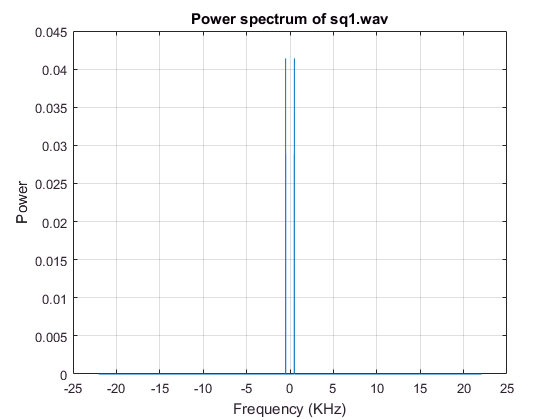

powerSpectrum('sq1.wav');

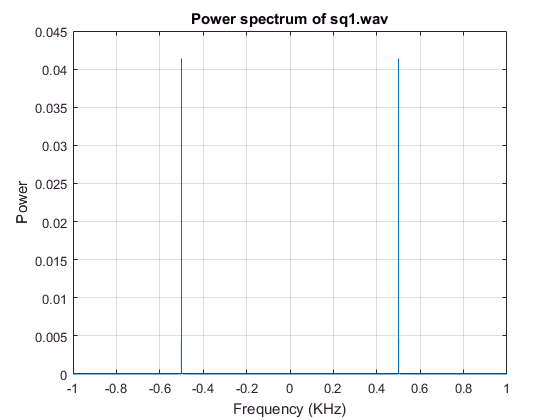

xlim([-1 1]);

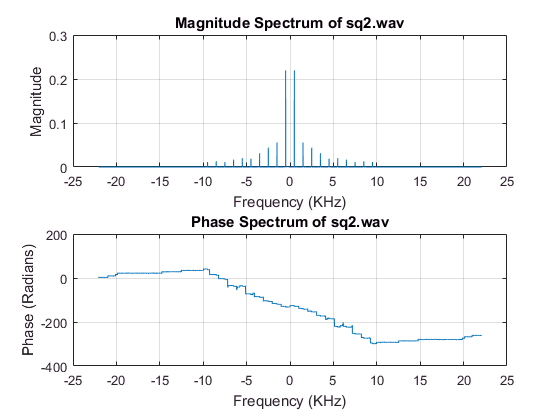

powerSpectrum('sq2.wav');

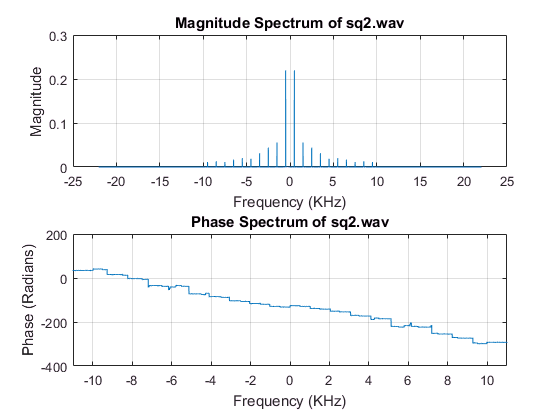

xlim([-11 11]);

[x1,Fs1]=audioread('sq1.wav');
p1=audioplayer(x1,Fs1);
[x2,Fs2]=audioread('sq2.wav');
p2=audioplayer(x2,Fs2);

play(p1);

play(p2);

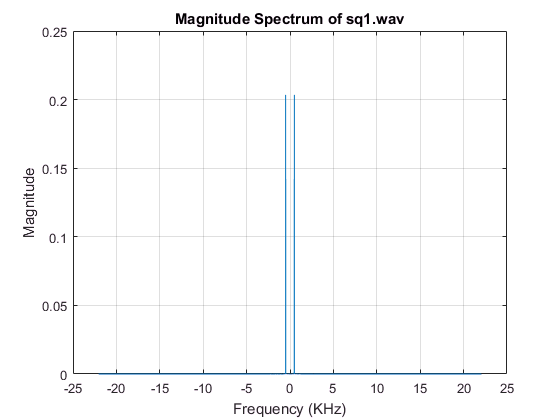

powerSpectrum('sq1.wav');

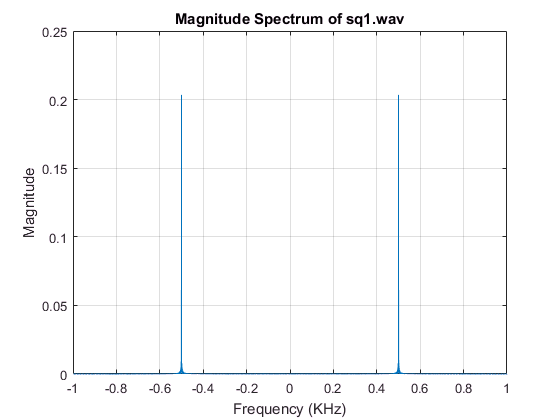

xlim([-1 1]);

powerSpectrum('sq2.wav');

xlim([-11 11]);

Fs=44100;
mag = [0.440 0.0 0.110 0.0 0.090 0.0 0.060 0.0 0.040];
ang = [-130 -130 -140 -140 -150 -150 -170 -170 -180];
Dn = mag.*exp(i*ang);

notes=[262, 262, 294, 262, 349, 330, 262, 262, 294, 262, 392, 349, 262, 262, 523, 440, 349, 330, 294, 466, 466, 440, 349, 392, 349];
duration=[0.5, 0.5, 1, 1, 1, 2, 0.5, 0.5, 1, 1, 1, 2, 0.5, 0.5, 1, 1, 1, 1, 3, 0.5, 0.5, 1, 1, 1, 2];

[x, Fs]=playMusicFS(notes, duration, Dn, Fs);
p=audioplayer(x,Fs);
play(p);

Fs=44100;
[x, Fs]=playMusicFS(notes, duration, Dn, Fs/2);
p=audioplayer(x,Fs/2);
play(p)

[x, Fs]=playMusicFS(notes, duration, Dn, Fs);
p=audioplayer(x,2*Fs);
play(p);

%S = 1000;
S=44100;
%S=1046;
%S=2092;
%note = @(f,d) 0.25*cos(2*pi*f*[0:1/S:d])+0.3*cos(2*pi*3*f*[0:1/S:d])+0.2*cos(2*pi*5*f*[0:1/S:d]);
% Note 2
note = @(f,d) 0.25*cos(2*pi*5*f*[0:1/S:d]);
%note = @(f,d) 0.5*cos(2*pi*f*[0:1/S:d])+0.35*cos(2*pi*2*f*[0:1/S:d])+0.6*cos(2*pi*3*f*[0:1/S:d])+0.05*cos(2*pi*4*f*[0:1/S:d])+0.05*cos(2*pi*0.05*f*[0:1/S:d]);
% Song 1
%fs = [330 294 262 294 330 330 330 294 294 294 330 392 392];
%ds = [0.5 0.5 0.5 0.5 0.5 0.5 0.75 0.5 0.5 0.75 0.5 0.5 0.75];
%Song 2
fs=[262, 262, 294, 262, 349, 330, 262, 262, 294, 262, 392, 349, 262, 262, 523, 440, 349, 330, 294, 466, 466, 440, 349, 392, 349];
ds=[0.5, 0.5, 1, 1, 1, 2, 0.5, 0.5, 1, 1, 1, 2, 0.5, 0.5, 1, 1, 1, 1, 3, 0.5, 0.5, 1, 1, 1, 2];

x = [];
for index=1:numel(fs)
x = [x note(fs(index), ds(index))];
end
player=audioplayer(x,S);
play(player)
%sound(x, S)
%plot(x)

calcpower('sq2.wav');

    0.1480



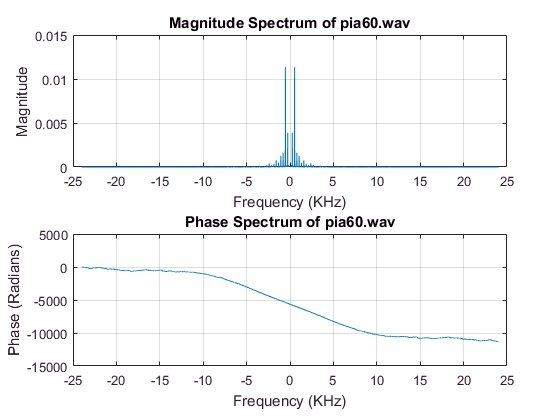

powerSpectrum('pia60.wav');

% from the plot
mag = [0.0039 0.0114 0.0015 0.0012 0.0008]; %[0.2 0.5 0.8 1.1 1.3]
ang = [-5600 -5800 -6000 -6200 -6400];
Dn = mag.*exp(1i*ang);

notes=[262, 262, 294, 262, 349, 330, 262, 262, 294, 262, 392, 349, 262, 262, 523, 440, 349, 330, 294, 466, 466, 440, 349, 392, 349];
duration=[0.5, 0.5, 1, 1, 1, 2, 0.5, 0.5, 1, 1, 1, 2, 0.5, 0.5, 1, 1, 1, 1, 3, 0.5, 0.5, 1, 1, 1, 2];

s = 44100;

[x, s]=playMusicFS(notes, duration, Dn, s);
p=audioplayer(x,s);
play(p)